5.1 a.) iii.) 

(s+c)^3 + A(Ts+1) = 0

Can a plot of the roots be drawn versus c for given constant values of and by any means at all?

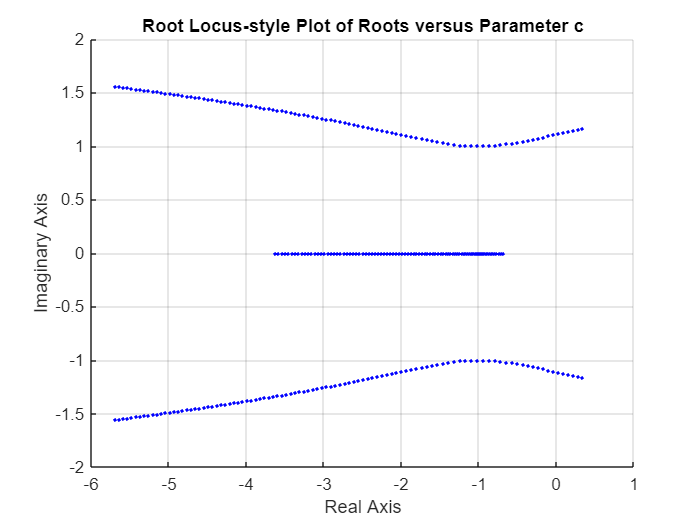

%% Written by AI, edited by Seth Ricks

A = 1;
T = 1;

% Define a range of values for c to sweep through
c_values = linspace(0, 5, 100); 

figure;
hold on;

for i = 1:length(c_values)
    c = c_values(i);
    
    poly_coeffs = [1, 3*c, 3*c^2 + A*T, c^3 + A];
   
    r = roots(poly_coeffs);
    
    % Plot the roots on the complex s-plane
    plot(real(r), imag(r), 'b.'); 
end

grid on;
xlabel('Real Axis');
ylabel('Imaginary Axis');
title('Root Locus-style Plot of Roots versus Parameter c');
hold off;